# Plan kurvebevægelse

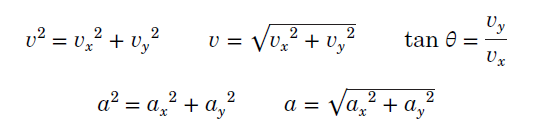

Formler

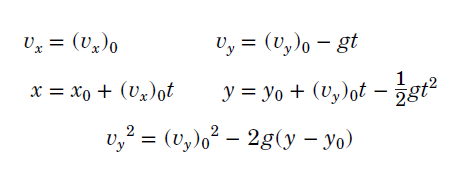

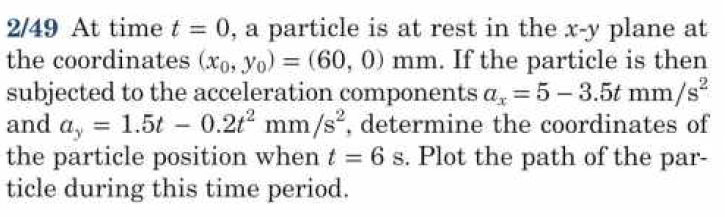

clear

u = symunit;

x0 = 60 

x0 =     60


y0 = 0

y0 =      0



syms t

ax = 5 - 3.5*t 

$$ax = 5-\frac{7\,t}{2}$$

vx = int(ax,t)

$$vx = -\frac{t\,\left(7\,t-20\right)}{4}$$

px = int(vx, t) + x0

$$px = 60-\frac{t^{2}\,\left(7\,t-30\right)}{12}$$



ay = 1.5*t - 0.2*t^2

$$ay = \frac{3\,t}{2}-\frac{t^{2}}{5}$$

vy = int(ay,t)

$$vy = -\frac{t^{2}\,\left(4\,t-45\right)}{60}$$

py = int(vy, t)

$$py = -\frac{t^{3}\,\left(t-15\right)}{60}$$


py1 = subs(py,t,6);
vpa(py1,3)

$$ans = 32.4$$

px1 = subs(px,t,6);
vpa(px1,3)

$$ans = 24.0$$

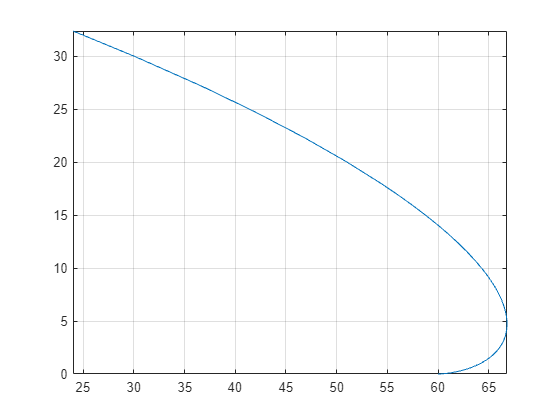



fplot(px,py, [0,6]), grid()

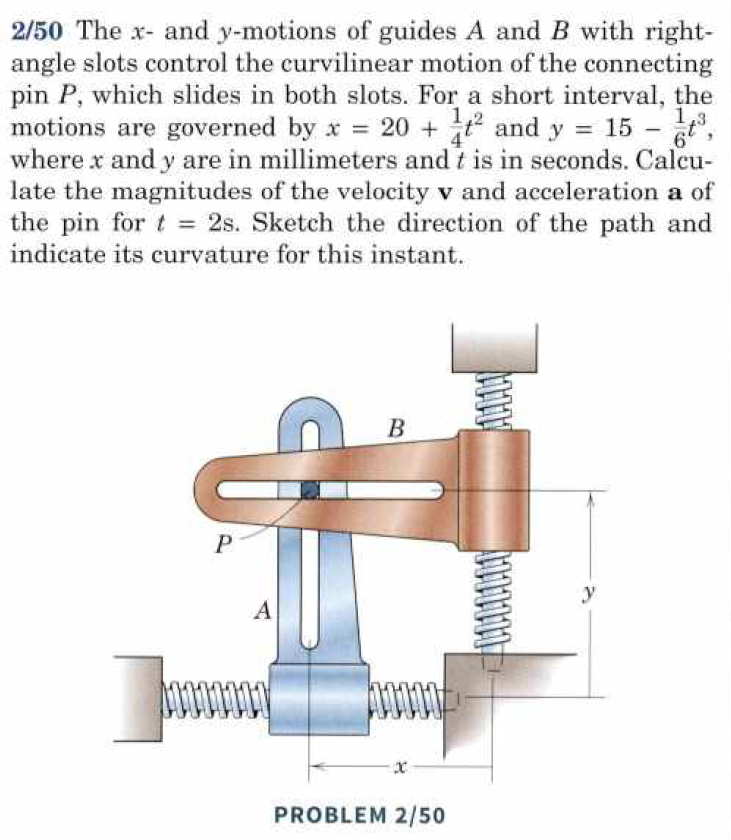

clear

syms t

px = 20 + 1/4 * t^2

$$px = \frac{t^{2}}{4}+20$$

vx = diff(px,t)

$$vx = \frac{t}{2}$$

ax = diff(vx,t)

$$ax = \frac{1}{2}$$


py = 15 - 1/6 * t^3

$$py = 15-\frac{t^{3}}{6}$$

vy = diff(py,t)

$$vy = -\frac{t^{2}}{2}$$

ay = diff(vy,t)

$$ay = -t$$


t_ny = 2

t_ny =      2



v_avg = sqrt(vx^2 + vy^2);
v_avg = vpa(subs(v_avg,t,t_ny),3)

$$v\_avg = 2.24$$


a_avg = sqrt(ax^2 + ay^2);
a_avg = vpa(subs(a_avg,t,t_ny),3)

$$a\_avg = 2.06$$

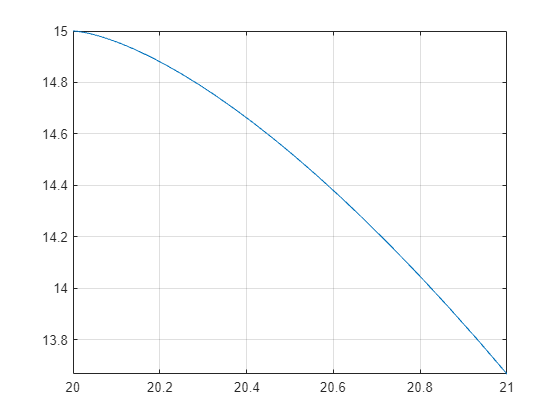





fplot(px,py,[0 2]), grid()

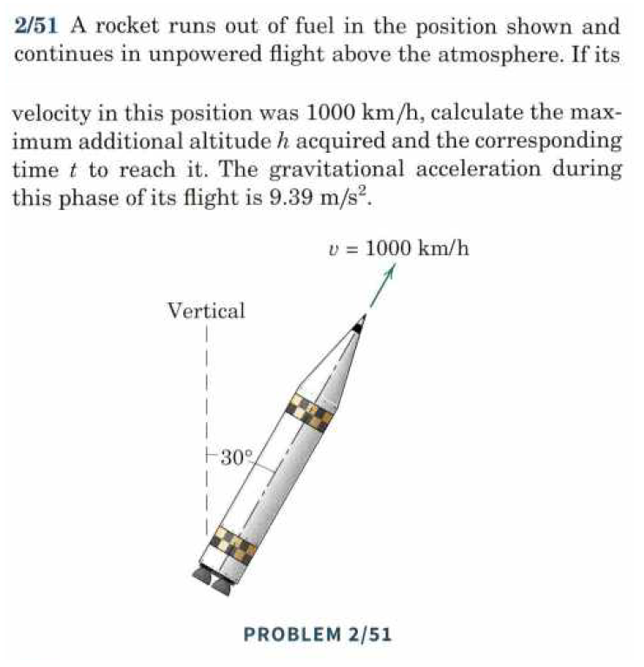

clear


v_y0 = 1000/3.6 * sind(60) % m/s

v_y0 =        240.56


v_x0 = 1000/3.6 * cosd(30) % m/s

v_x0 =        240.56


% g er negativ
g = -9.39 % m/s^2

g =         -9.39




syms t 

% Tiden findes

v_y = v_y0 + g*t == 0;

t = solve(v_y, t);
t = vpa(t, 3)

$$t = 25.6$$


% Positionen findes
Sx = 1/2*g*t^2 + v_x0*t + 0;
Sx = vpa(Sx, 3) % m

$$Sx = 3080.0$$

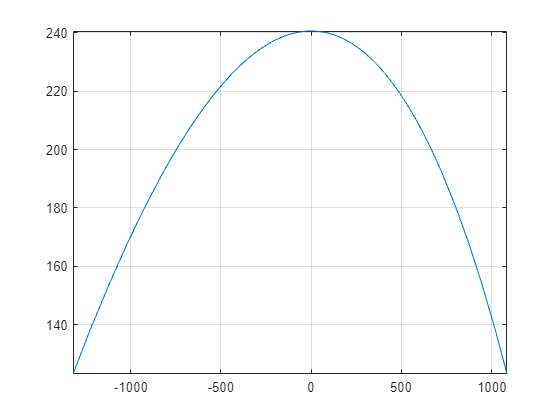


% Plot for sjov når den rammer jorden
clear t
syms t
y0 = 0;
Sy = 1/2*g*t^2 + v_y0 + y0;
Sx = 1/2*g*t^2 + v_x0*t + 0;

fplot(Sx, Sy), grid()

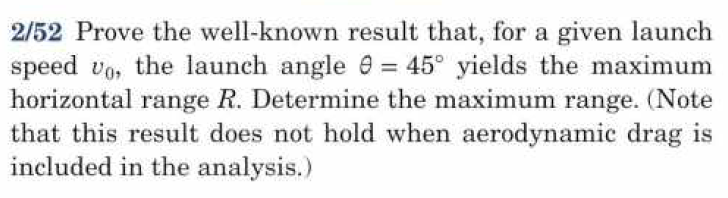

Se gammel notebook uden bagside for løsning

Det vigtige takeaway er følgende:

Hvis affyringsvinklen er 45 grader


$$R_{max} = \frac{v_0^2}{g}$$


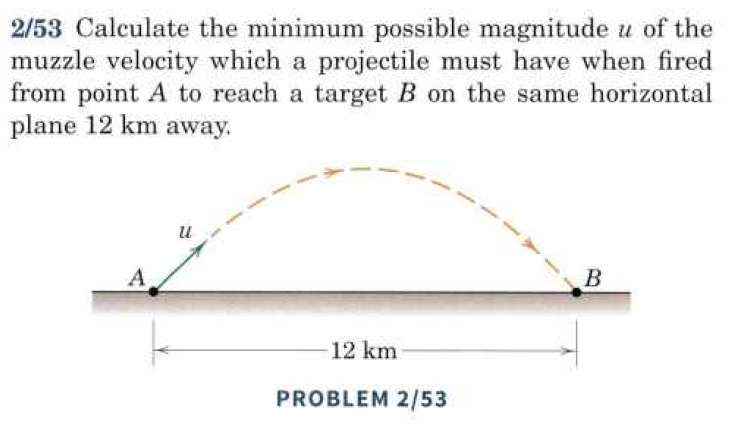

I den her opgave bruges resultatet fra forgående opgave

clear

R = 12000 % m

R =        12000


g = 9.81 % m/s^2

g =          9.81



syms v0
eq = R == v0^2/g;

v0 = solve(eq, v0);
v0 = vpa(v0, 3)

$$v0 = \left(\begin{array}{c} -343.0\\ 343.0 \end{array}\right)$$

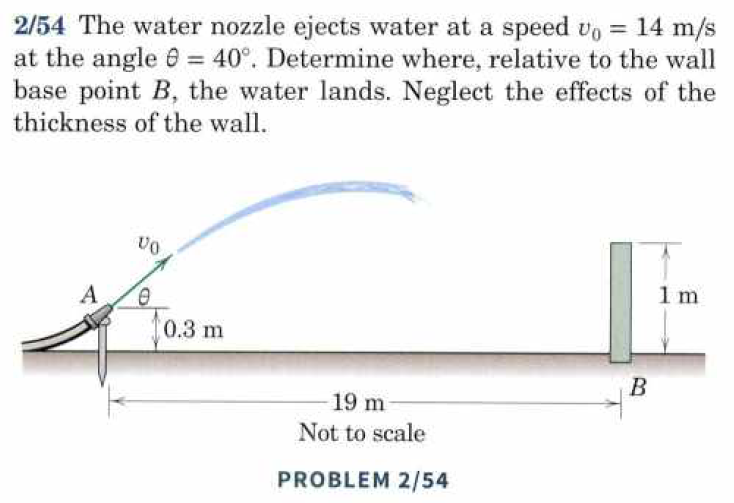

clear
format shortG

v0 = 14;    theta = 40; y0 = 0.3;   x0 = 0; R = 19;

g = -9.81;

syms t
% hastigheder

v0_y = sind(theta) * v0

v0_y =         8.999


v0_x = cosd(theta) * v0

v0_x =        10.725



% Positioner

Sy = 1/2*g*t^2 + v0_y*t + y0;

Sx = v0_x*t + x0;

% Der løses for tiden 
Sx = v0_x*t + x0 == R

$$Sx = \frac{3018712785007385\,t}{281474976710656}=19$$


t = solve(Sx, t);
t = vpa(t,4)

$$t = 1.772$$


% Tiden indsættes i formlen for y efter tiden t
Sy = 1/2*g*t^2 + v0_y*t + y0;
vpa(Sy,3)

$$ans = 0.848$$

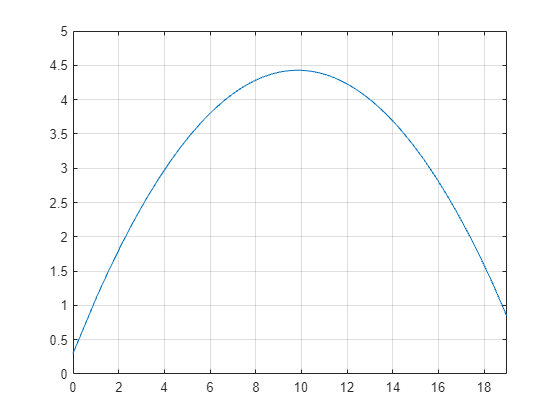



clear t

syms t

Sy = 1/2*g*t^2 + v0_y*t + y0;

Sx = v0_x*t + x0;

fplot(Sx,Sy), xlim([0, 19]), ylim([0,5]), grid()

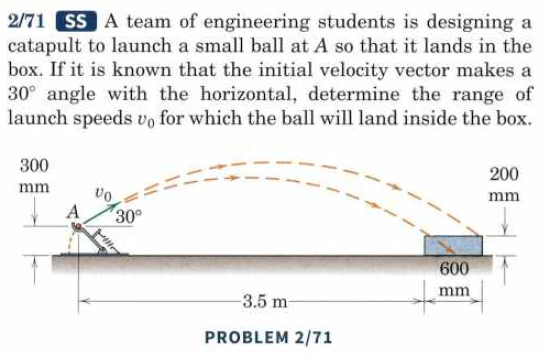

clear


theta = deg2rad(30);
g = -9.81;
R = 3.5;

y0 = 0;
ys = -0.1;
x0 = 0;

syms v0 t



Sx = x0 + v0*cos(theta)*t == R;
Sy = 1/2*g*t^2 + v0*sin(theta)*t + y0 == ys;


[v0, t] = solve([Sx Sy], [v0, t]);

vpa(max(v0), 3)

$$ans = 6.15$$

vpa(max(t), 3)

$$ans = 0.658$$


%%%%%
clear all 


theta = deg2rad(30);
g = -9.81;
R = 4.1;

y0 = 0;
ys = -0.1;
x0 = 0;

syms v0 t



Sx = x0 + v0*cos(theta)*t == R;
Sy = 1/2*g*t^2 + v0*sin(theta)*t + y0 == ys;


[v0, t] = solve([Sx Sy], [v0, t]);

vpa(max(v0), 3)

$$ans = 6.68$$

vpa(max(t), 3)

$$ans = 0.709$$

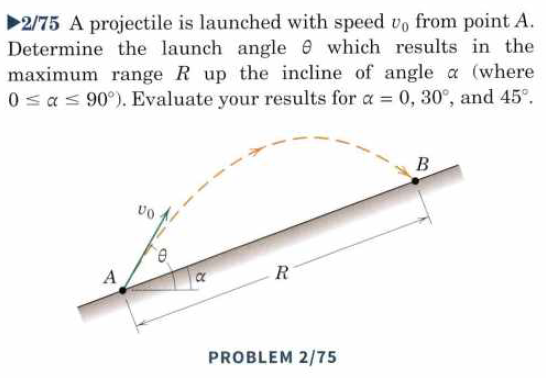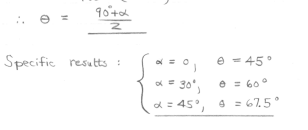

Godt resultat at have

$$ans = \max\left(\left[-\frac{981\,\sqrt{-\frac{800\,R\,\left(\cos\left(\theta \right)-\sin\left(\theta \right)\right)}{981\,\cos\left(\theta \right)}}}{400\,\left(\cos\left(\theta \right)-\sin\left(\theta \right)\right)},\frac{981\,\sqrt{-\frac{800\,R\,\left(\cos\left(\theta \right)-\sin\left(\theta \right)\right)}{981\,\cos\left(\theta \right)}}}{400\,\left(\cos\left(\theta \right)-\sin\left(\theta \right)\right)}\right],\left[\right],2,\text{"omitnan"},R\notin \mathbb{R}\vee \theta \notin \mathbb{R}\right)$$

$$ans = \max\left(\left[-\frac{\sqrt{-\frac{800\,R\,\left(\cos\left(\theta \right)-\sin\left(\theta \right)\right)}{981\,\cos\left(\theta \right)}}}{2},\frac{\sqrt{-\frac{800\,R\,\left(\cos\left(\theta \right)-\sin\left(\theta \right)\right)}{981\,\cos\left(\theta \right)}}}{2}\right],\left[\right],2,\text{"omitnan"},R\notin \mathbb{R}\vee \theta \notin \mathbb{R}\right)$$